rng(5)
pwlregions_init
gcp;
net = RandomPWANetwork(2,[10,5])

regs = net.pwa('input_space', makebox(2,5), 'max_depth', i);
lens = arrayfun(@(x) size(x.H,1), regs);
max_depth = max(lens)
for i = 1:max_depth+1
    net.pwa('input_space', makebox(2,5), 'max_depth', i)
    figure;
    net.plot_output(1)
end


rng(0239)
bignet = RandomPWANetwork(2,[50,20,20])
regs = bignet.pwa('input_space', makebox(2,5), 'max_depth', 10)
plot(regs)


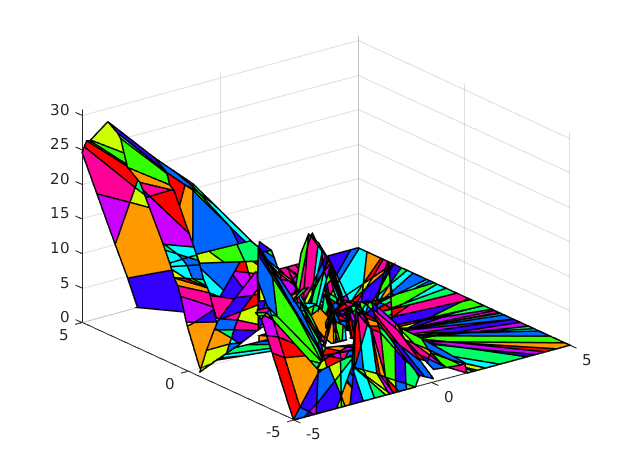

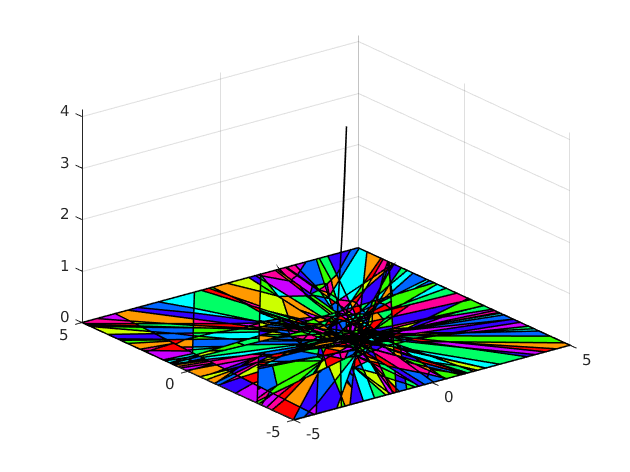

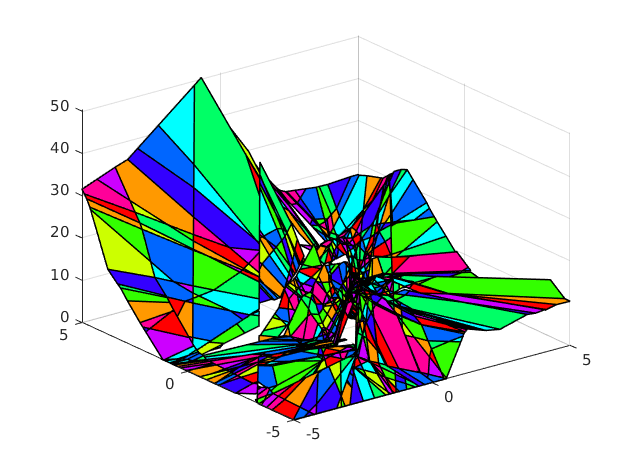

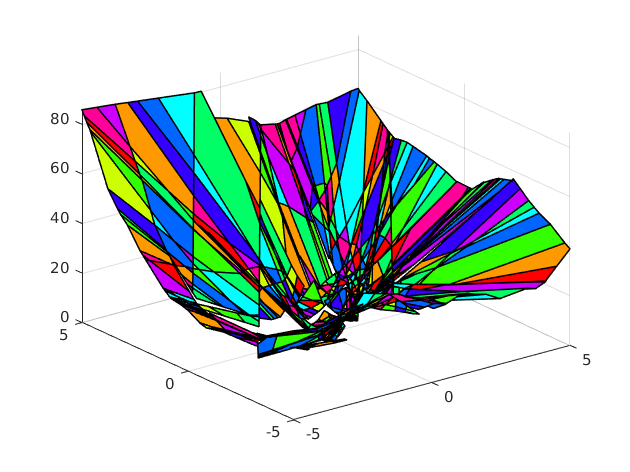

for i = 1:4
    figure
    bignet.plot_output(i)
end

regs

truncated = arrayfun(@(x) isfield(x.Data, 'truncate'), regs);
plot( truncated)

depths = arrayfun(@(x) x.truncate, regs(truncated));
max(depths)